# Internet Speed Test

clc; clear; close all;

## Theoretical values

Enter below the theoretical download  and upload values in Mb/s.

% download theoretical speed
th_download = 20;
% upload theoretical speed
th_upload = 1;

## Dataset name

Enter below the dataset name. The file should contain a single json array.

fname = 'data/ee-uk.json';

## Load data

Load the data into memory.

fid = fopen(fname);
raw = fread(fid,inf);
str = char(raw');
json = jsondecode(str);

## Display data

Display the data structure and the json string.

disp('Loaded data structure:');

Loaded data structure:


disp(json);

  87×1 struct array with fields:

    bytes_sent
    download
    timestamp
    share
    bytes_received
    ping
    upload
    server



disp('Raw json data:');

Raw json data:


disp(str);

[{"bytes_sent": 2318336, "download": 14473858.084061086, "timestamp": "2017-12-12T19:00:09.499991Z", "share": "http://www.speedtest.net/result/6873422558.png", "bytes_received": 18237740, "ping": 49.913, "upload": 1188798.1302517003, "server": {"latency": 49.913, "name": "London", "url": "http://speedtest.vodafone.co.uk/speedtest/upload.php", "country": "Great Britain", "lon": "-0.1062", "cc": "GB", "host": "speedtest.vodafone.co.uk:8080", "sponsor": "Vodafone UK", "url2": "http://speedtest-newbury.vodafone.co.uk/speedtest/upload.php", "lat": "51.5171", "id": "2789", "d": 3.128998962486338}}
,
{"bytes_sent": 2048000, "download": 3267894.2835351843, "timestamp": "2017-12-12T20:00:09.696934Z", "share": "http://www.speedtest.net/result/6873589095.png", "bytes_received": 4591592, "ping": 18.86, "upload": 1119565.0257343885, "server": {"latency": 18.86, "name": "London", "url": "http://speedtest.vodafone.co.uk/speedtest/upload.php", "country": "Great Britain", "lon": "-0.1062", "cc": "GB", 

## Extract data

Extract download, upload and timestamp information, and store each of them into a vector. Also, convert the speed into Mb/s.

% number of samples
m = size(json(:),1);

% format and scale downloads & uploads samples
downloads = [json(:).download]' * 1e-6;
uploads = [json(:).upload]' * 1e-6;

% format and convert timestamps to keep only hours
time = zeros(m,1);
for i=1:m
    timestamp = json(i).timestamp;
    [~,~,~,H,MN,~] = datevec(datenum8601(timestamp));
    if MN < 30
        time(i) = H;
    else
        time(i) = H+1;
    end
end

## Aggregate data

Aggregate speed for the same hour of the day; compute the mean and standard devisation for each hour.

% download speed
download_aggr = zeros(24,2);
for i=0:23
    tmp = downloads(time==(i));
    download_aggr(i+1,1) = mean(tmp);
    download_aggr(i+1,2) = std(tmp);
end

% upload speed
upload_aggr = zeros(24,2);
for i=0:23
    tmp = uploads(time==(i));
    upload_aggr(i+1,1) = mean(tmp);
    upload_aggr(i+1,2) = std(tmp);
end

## Plot

Plot the aggregated result.

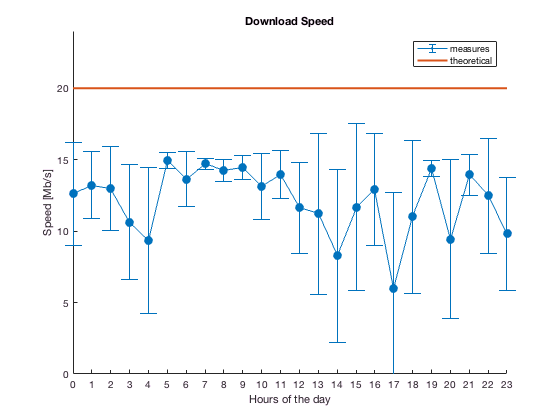

% plot download speed
error_plot(...
    (0:1:23),...
    download_aggr(:,1),...
    download_aggr(:,2),...
    th_download, ...
    'Download Speed'...
);

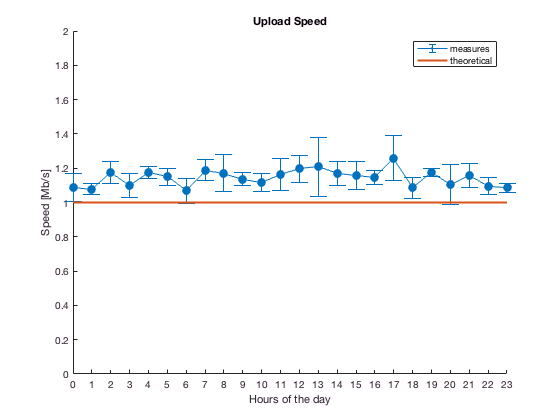


% plot upload speed
error_plot(...
    (0:1:23),...
    upload_aggr(:,1),...
    upload_aggr(:,2),...    
    th_upload,...
    'Upload Speed'...
);